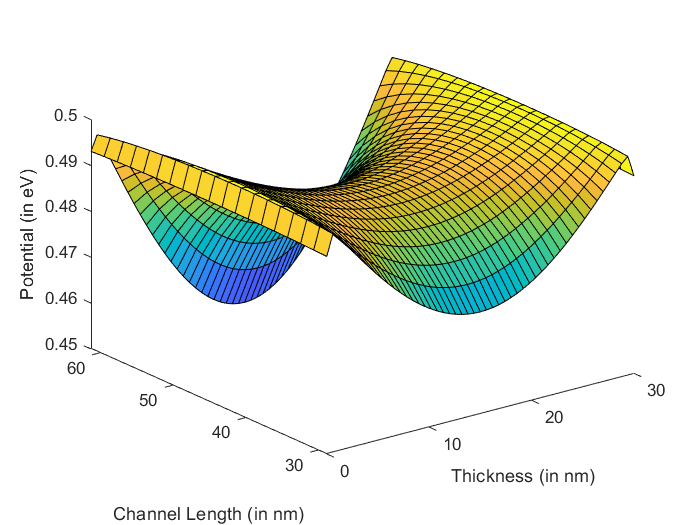

%dimensions
Hfin = 30 ;
Tfin = 30 ;
Lch = 90 ;
Teff = Tfin*1e-9 ;
Heff = Hfin*1e-9 ;
Leff = Lch*1e-9 ;

%voltages
Vg = 0; Vtg = 0; Vfg = 0; Vbg = 0;
Vfb = 0.5;
phi_ms = 0;
Vds = 0.4;


%boundaries' voltage values
% I have declared all these boundary voltages so we can have the plots for each of them  separately as well
phi_tg=0; phi_fg=0; phi_bg=0; phi_s=0; phi_d=0; phi_bo=0; 
V=0; 

for m = 1:50
    for n = 1:50
       %these are matrices so when we multiply them then no. of columns of A should be equal to no. of rows of B.
       %  if it is not so then we should do A' * B, i.e., A transpose * B
      
        x=0:(Teff/50):Teff; % 1 row 50 columns  so x'*y is 50x50 matrix and x*y' is 1x1 matrix i.e. = scalar
        y=0:(Leff/50):Leff; % 1 row 50 columns  so y'*x = 50x50 matrix and y*x' is 1x1 matrix i.e. = scalar
        z=0;      % 1x1 matrix i.e. a scalar
        
        % % z=0 implies for the bottom plane we are seeing, i.e above BO
        
        ym = ((2*m-1)*pi)/Leff;
        xn = ((2*n-1)*pi)/Teff;
        zn = ((2*n-1)*pi)/(2*Heff);
        xm = ((2*m-1)*pi)/Teff;
        
        Kx = sqrt( ((2*m-1)/Leff)^2 + ((2*n-1)/(2*Heff))^2 ) * Teff ;
        Ky = sqrt( ((2*m-1)/Teff)^2 + ((2*n-1)/(2*Heff))^2 ) * Leff ;
        Kz = sqrt( ((2*n-1)/Teff)^2 + ((2*m-1)/(Leff))^2 ) * Heff ;
        
        kz_by_h = (Kz*pi)/Heff;
        kx_by_t = (Kx*pi)/Teff;
        ky_by_l = (Ky*pi)/Leff;
        
        constt = 16/( (2*n-1)*(2*m-1)*pi*pi) ;
        
        % here yn,xn,xm,zn all these will be matrices so their sine or cosine will also be matrices 
        % we are taking the multiplication uniformly y'*x (and z is a scalar so its order doesnt matter) or we could follow x'*y
        % if we had followed x*y' or y*x' then we would have got a 1x1 matrix i.e. a scalar hence we couldn't plot
        
        phi_tg = phi_tg + (constt*(Vtg-Vfb))*(sin(ym*y))'*(sin(xn*x))*( cosh(kz_by_h*z) / cosh(Kz*pi) ) ;
        
        phi_fg = phi_fg + ( constt*(Vfg-Vfb) * ((-1)^(n+1)) )* (sin(ym*y))'*( sinh(kx_by_t*x) / sinh(Kx*pi) )*(cos(zn*z)) ;
        phi_bg = phi_bg + ( constt*(Vbg-Vfb) * ((-1)^(n+1)) )*(sin(ym*y))'*( sinh((kx_by_t)*(Teff-x)) / sinh(Kx*pi) )*cos(zn*z) ;
        
        phi_s = phi_s + ( (-1)*constt*phi_ms*((-1)^(n+1)) )*( sinh((ky_by_l)*(Leff-y)) / sinh(Ky*pi) )'*(sin(xm*x))*cos(zn*z) ;
        phi_d = phi_d + ( (-1)*constt*(phi_ms-Vds)*((-1)^(n+1)) )*( sinh(ky_by_l*y) / sinh(Ky*pi) )'*(sin(xm*x))*cos(zn*z) ;
        
        phi_bo = 0;
        
         % I am doing summation at individual boundaries only so ath the end of the loop we have the overall V plot
         % as well as all the boundary voltages plots
  
      
    end
end

V =  V + phi_tg + phi_bg + phi_fg + phi_s + phi_d + phi_bo;




% Overall
surf(x/1e-9, y/1e-9, -V); grid;
xlabel('Thickness (in nm)');
ylabel('Channel Length (in nm)');
zlabel('Potential (in eV)');

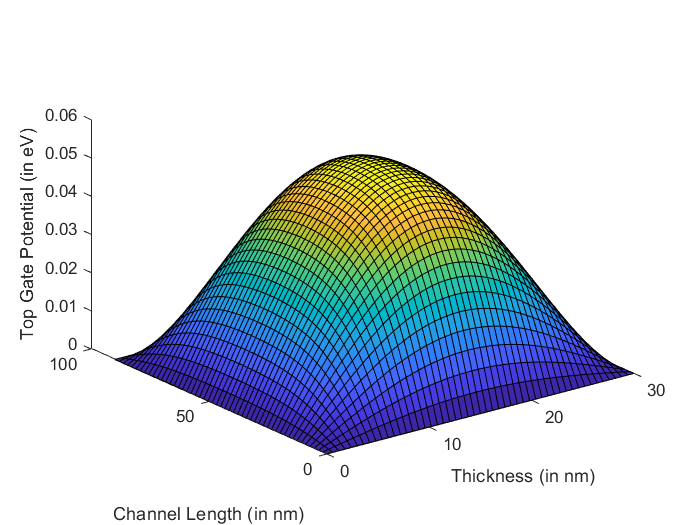


% Top Gate
surf(x/1e-9, y/1e-9, -phi_tg); grid;
xlabel('Thickness (in nm)');
ylabel('Channel Length (in nm)');
zlabel('Top Gate Potential (in eV)');

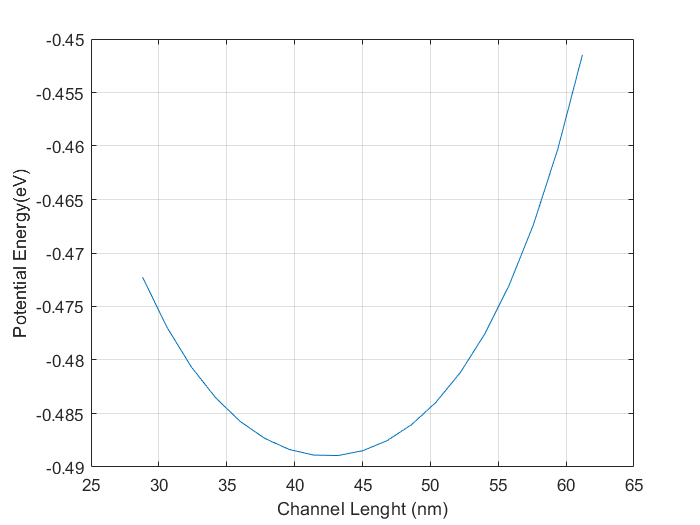




% to plot a particular x-cut what we do is plot all the V values from the matrix corresponding to the column length(x)/2
% i.e. basically the distribution of V at mid of the fin width and z plane we decide inside the for loop
% z=0 plane implies the botttom side, z=Heff/2 would correspond to centre of the fin

plot(y/1e-9,V(:,25)); % this is basic matrix (row,col) indexing "V(:, length(x)/2)" means all rows in the column length(x)/2 in V matrix
                  
grid;
xlabel('Channel Lenght (nm)');
ylabel('Potential Energy(eV)');